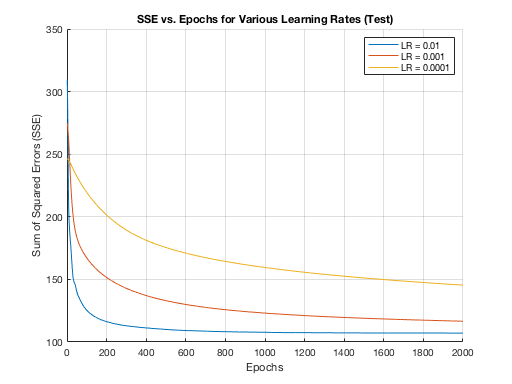

clc;
clear;
% Load and preprocess the data
data = readtable('Plates 2.csv');
X = data{1:end, 1:27}; % Features
y = data{1:end, 28}; % Fault categories

% Convert fault categories to one-hot encoded format
numClasses = 7;
y_onehot = zeros(size(y, 1), numClasses);
for i = 1:size(y, 1)
    y_onehot(i, y(i)) = 1;
end

% Split the data into training (70%), validation (15%), and test (15%) sets
n = size(X, 1);
idx = randperm(n);
X_train = X(idx(1:round(0.7*n)), :);
y_train = y_onehot(idx(1:round(0.7*n)), :);
X_val = X(idx(round(0.7*n)+1:round(0.85*n)), :);
y_val = y_onehot(idx(round(0.7*n)+1:round(0.85*n)), :);
X_test = X(idx(round(0.85*n)+1:end), :);
y_test = y_onehot(idx(round(0.85*n)+1:end), :);

% Normalize the features
mu = mean(X_train);
sigma = std(X_train);
X_train = (X_train - mu) ./ sigma;
X_val = (X_val - mu) ./ sigma;
X_test = (X_test - mu) ./ sigma;

% Neural network architecture
inputSize = size(X_train, 2);
hiddenLayerSize = 64;
outputSize = numClasses;

% Define training parameters
numEpochs = 2000;
momentum = 0.9;
lambda = 0.001; % Regularization parameter (weight decay)
dynamicLearningRateFactor = 0.9; % Factor to reduce learning rate dynamically

% Different initialization techniques
initializationTechniques = {'Xavier', 'Dynamic Learning Rate', 'Weight Decay'};

% Define learning rates to test
learningRates = [0.01, 0.001, 0.0001];
numLearningRates = length(learningRates);

% Initialize variables to store SSE values
sse_train = zeros(numEpochs, length(initializationTechniques));
sse_test = zeros(numEpochs, length(initializationTechniques));
accuracy_train = zeros(numLearningRates, length(initializationTechniques));
accuracy_test = zeros(numLearningRates, length(initializationTechniques));
sse_lr = zeros(numEpochs, numLearningRates);

% Loop over each initialization technique
for init_index = 1:length(initializationTechniques)
    % Initialization techniques
    if strcmp(initializationTechniques{init_index}, 'Xavier')
        weightInitFunc = @(inputSize, hiddenLayerSize) ...
            randn(inputSize, hiddenLayerSize) * sqrt(1 / inputSize);
        outputInitFunc = @(hiddenLayerSize, outputSize) ...
            randn(hiddenLayerSize, outputSize) * sqrt(1 / hiddenLayerSize);
    elseif strcmp(initializationTechniques{init_index}, 'Dynamic Learning Rate')
        weightInitFunc = @(inputSize, hiddenLayerSize) ...
            randn(inputSize, hiddenLayerSize) * sqrt(2 / inputSize);
        outputInitFunc = @(hiddenLayerSize, outputSize) ...
            randn(hiddenLayerSize, outputSize) * sqrt(2 / hiddenLayerSize);
    elseif strcmp(initializationTechniques{init_index}, 'Weight Decay')
        weightInitFunc = @(inputSize, hiddenLayerSize) ...
            randn(inputSize, hiddenLayerSize) * sqrt(2 / inputSize);
        outputInitFunc = @(hiddenLayerSize, outputSize) ...
            randn(hiddenLayerSize, outputSize) * sqrt(2 / hiddenLayerSize);
    end
    
    % Loop over each learning rate for the baseline model
    for lr_index = 1:numLearningRates
        learningRate = learningRates(lr_index);
        currentLearningRate = learningRate;

        % Initialize weights and biases
        W1 = weightInitFunc(inputSize, hiddenLayerSize);
        W2 = outputInitFunc(hiddenLayerSize, outputSize);
        b1 = zeros(1, hiddenLayerSize);
        b2 = zeros(1, outputSize);

        % Gradient descent with momentum and weight decay
        vW1 = zeros(size(W1));
        vb1 = zeros(size(b1));
        vW2 = zeros(size(W2));
        vb2 = zeros(size(b2));
        
        for epoch = 1:numEpochs
            % Forward pass
            Z1 = X_train * W1 + b1;
            A1 = max(0, Z1); % ReLU activation
            Z2 = A1 * W2 + b2;
            A2 = exp(Z2) ./ sum(exp(Z2), 2); % Output layer with softmax activation

            % Compute SSE for this epoch (training)
            sse_train(epoch, init_index) = sum(sum((y_train - A2).^2));

            % Backward pass
            dZ2 = A2 - y_train;
            dW2 = (A1' * dZ2) / size(X_train, 1) + lambda * W2;
            db2 = sum(dZ2) / size(X_train, 1);

            dA1 = dZ2 * W2';
            dZ1 = dA1 .* (Z1 > 0); % Derivative of ReLU
            dW1 = (X_train' * dZ1) / size(X_train, 1) + lambda * W1;
            db1 = sum(dZ1) / size(X_train, 1);

            % Update weights with momentum and weight decay
            vW2 = momentum * vW2 - currentLearningRate * dW2;
            vb2 = momentum * vb2 - currentLearningRate * db2;
            vW1 = momentum * vW1 - currentLearningRate * dW1;
            vb1 = momentum * vb1 - currentLearningRate * db1;

            W2 = W2 + vW2;
            b2 = b2 + vb2;
            W1 = W1 + vW1;
            b1 = b1 + vb1;

            % Dynamic learning rate adjustment
            if strcmp(initializationTechniques{init_index}, 'Dynamic Learning Rate')
                currentLearningRate = currentLearningRate * dynamicLearningRateFactor;
            end

            % Forward pass for the test set
            Z1_test = X_test * W1 + b1;
            A1_test = max(0, Z1_test);
            Z2_test = A1_test * W2 + b2;
            A2_test = exp(Z2_test) ./ sum(exp(Z2_test), 2);

            % Compute SSE for this epoch (test)
            sse_lr(epoch, lr_index) = sum(sum((y_test - A2_test).^2));
        end

        % Compute accuracy for baseline model
        [~, predictedTrain] = max(A2, [], 2);
        [~, trueTrain] = max(y_train, [], 2);
        accuracy_train(lr_index, init_index) = mean(predictedTrain == trueTrain) * 100;

        [~, predictedTest] = max(A2_test, [], 2);
        [~, trueTest] = max(y_test, [], 2);
        accuracy_test(lr_index, init_index) = mean(predictedTest == trueTest) * 100;
    end
end

% Plot SSE vs. Learning Rates for the baseline model (Test)
figure;
hold on;
for lr_index = 1:numLearningRates
    plot(1:numEpochs, sse_lr(:, lr_index), 'DisplayName', ['LR = ', num2str(learningRates(lr_index))]);
end
xlabel('Epochs');
ylabel('Sum of Squared Errors (SSE)');
title('SSE vs. Epochs for Various Learning Rates (Test)');
legend;
grid on;
hold off;

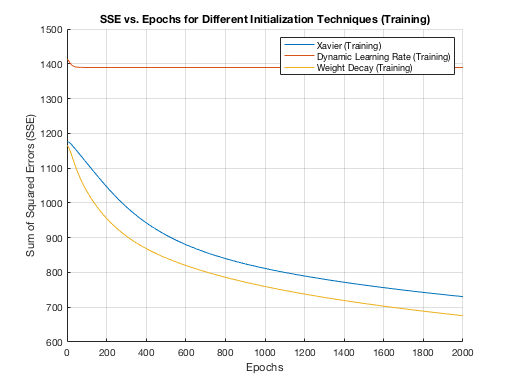


% Plot SSE vs. Epochs for different initialization techniques (Training)
figure;
hold on;
for init_index = 1:length(initializationTechniques)
    plot(1:numEpochs, sse_train(:, init_index), 'DisplayName', [initializationTechniques{init_index}, ' (Training)']);
end
xlabel('Epochs');
ylabel('Sum of Squared Errors (SSE)');
title('SSE vs. Epochs for Different Initialization Techniques (Training)');
legend;
grid on;
hold off;

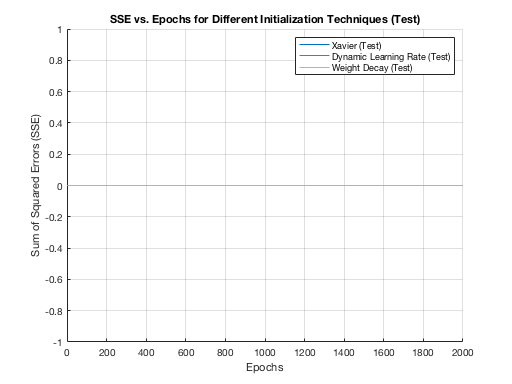


% Plot SSE vs. Epochs for different initialization techniques (Test)
figure;
hold on;
for init_index = 1:length(initializationTechniques)
    plot(1:numEpochs, sse_test(:, init_index), 'DisplayName', [initializationTechniques{init_index}, ' (Test)']);
end
xlabel('Epochs');
ylabel('Sum of Squared Errors (SSE)');
title('SSE vs. Epochs for Different Initialization Techniques (Test)');
legend;
grid on;
hold off;


% Display accuracy percentages for training and testing sets
fprintf('Percentage of Correct Predictions:\n');

Percentage of Correct Predictions:


fprintf('Learning Rate | Initialization | Training Accuracy | Test Accuracy\n');

Learning Rate | Initialization | Training Accuracy | Test Accuracy


for init_index = 1:length(initializationTechniques)
    for lr_index = 1:numLearningRates
        fprintf('%.5f | %s | %.2f%% | %.2f%%\n', learningRates(lr_index), initializationTechniques{init_index}, accuracy_train(lr_index, init_index), accuracy_test(lr_index, init_index));
    end
end

0.01000 | Xavier | 80.53% | 74.04%
0.00100 | Xavier | 75.41% | 69.12%
0.00010 | Xavier | 59.40% | 58.95%
0.01000 | Dynamic Learning Rate | 50.90% | 55.44%
0.00100 | Dynamic Learning Rate | 35.41% | 36.49%
0.00010 | Dynamic Learning Rate | 11.50% | 15.09%
0.01000 | Weight Decay | 80.53% | 73.33%
0.00100 | Weight Decay | 75.94% | 70.18%
0.00010 | Weight Decay | 63.23% | 60.70%
